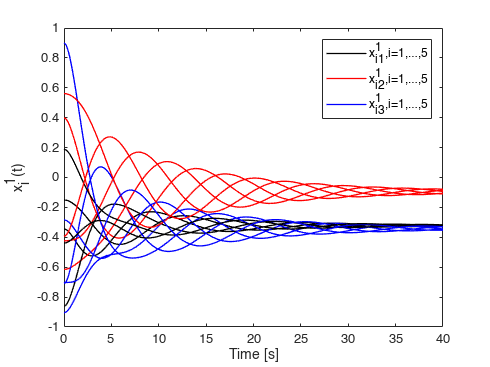

global L d
n = 5; m = 10; d = 3; scale = 1;

% G1: balanced graph
s = [1 1 2 2 3 3 4 4 5 5];
t = [2 3 3 4 4 5 5 1 1 2];
G1 = graph(s,t); %plot(G1);
A1 = [1 0 0;
      0 1 0;
      0 0 0];
A2 = [0 0 0;
      0 0 0;
      0 0 1];
Z = zeros(3,3);
A = [Z  A1  A2   Z   Z;
     Z   Z  A1  A2   Z;
     Z   Z   Z  A1  A2;
     A2  Z   Z   Z  A1;
     A1 A2   Z   Z   Z];
dg = A*(kron(ones(5,1),eye(3)));
D = blkdiag(dg(1:3,1:3),dg(4:6,1:3),dg(7:9,1:3),dg(10:12,1:3),dg(13:15,1:3));
L = D - A;
rng(1)
x0 = [];                        % the agents are initially located on the unit sphere
for i = 1:5
    r = 2*(rand(3,1)-0.5);
    x0 = [x0;r/norm(r)];        
end
x0 = [x0;zeros(15,1)];
[t,x] = ode45(@consensus,[0:0.1:40],x0);
x = x';
x1 = x(1:15,:);
x2 = x(16:30,:);
e = zeros(1,length(t));
for i=1:length(t)
    e(1,i) = norm(L*x1(:,i),2);
end
% plotting the states versus time
figure
hold on;
for i=1:5
   plot(t,x1(3*i-2,:),'-k','LineWidth',1);
   plot(t,x1(3*i-1,:),'-r','LineWidth',1);
   plot(t,x1(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i^1(t)';
box on;
legend({'x_{i1}^1,i=1,\ldots,5','x_{i2}^1,i=1,\ldots,5','x_{i3}^1,i=1,\ldots,5'},"NumColumns",1)

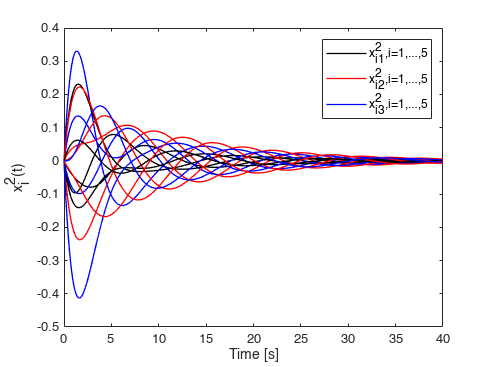


figure
hold on;
for i=1:5
   plot(t,x2(3*i-2,:),'-k','LineWidth',1);
   plot(t,x2(3*i-1,:),'-r','LineWidth',1);
   plot(t,x2(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i^2(t)';
box on;
legend({'x_{i1}^2,i=1,\ldots,5','x_{i2}^2,i=1,\ldots,5','x_{i3}^2,i=1,\ldots,5'},"NumColumns",1)

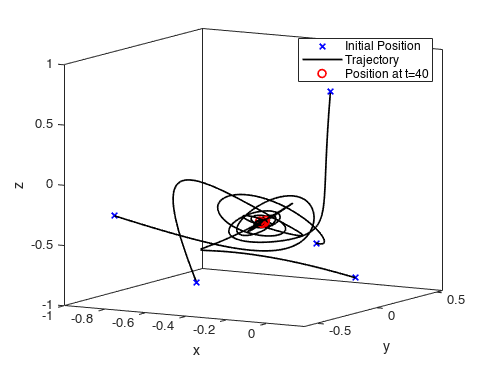



figure
hold on;
for i=1:5
   plot3(x(3*i-2,1),x(3*i-1,1),x(3*i,1),'xb','LineWidth',1.25);
   plot3(x(3*i-2,:),x(3*i-1,:),x(3*i,:),'-k','LineWidth',1.25);
   plot3(x(3*i-2,end),x(3*i-1,end),x(3*i,end),'or','LineWidth',1.25);
end
xlabel 'x'; ylabel 'y'; zlabel 'z';
box on
legend({'Initial Position','Trajectory','Position at t=40'},"NumColumns",1)
view(30,10)

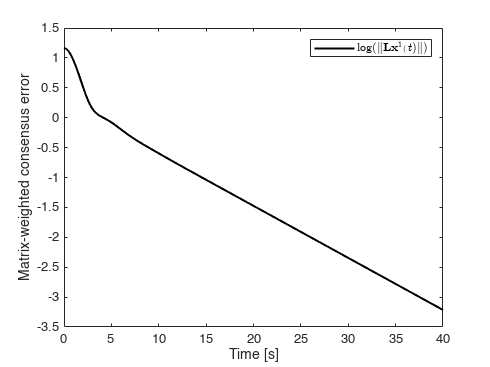


figure
plot(t,log(e)','-k','LineWidth',1.5)
xlabel 'Time [s]'; ylabel 'Matrix-weighted consensus error';
box on; 
legend({'$\log(\|\mathbf{L}\mathbf{x}^1(t)\|)$'},"Interpreter",'latex',"NumColumns",1)

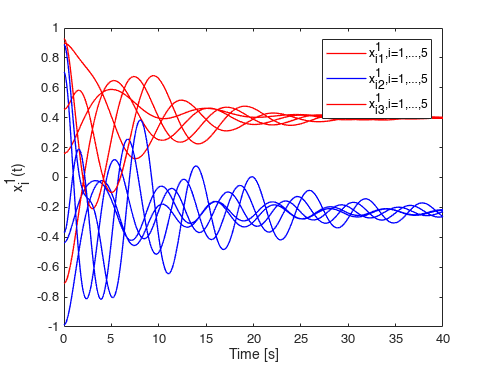



% G2: genralized balance graph

s = [1 1 2 3 4 4 5 5];
t = [2 3 3 4 5 5 1 2];
G2 = graph(s,t); % plot(G2);
A15 = eye(2); A25 = [0 0;0 1]; A43 = [2 0;0 4]; A54 = A43;
A21 = 0.5*[1 1; 1 0]; A32 = [1 1;1 2]; A31 = [1 -1;-1 2];
Z = zeros(2,2);
A = [Z Z Z Z A15;
    A21 Z Z Z A25;
    A31 A32 Z Z Z;
    Z Z A43 Z Z;
    Z Z Z A54 Z];
dg = A*(kron(ones(5,1),eye(2)));
D = blkdiag(dg(1:2,1:2),dg(3:4,1:2),dg(5:6,1:2),dg(7:8,1:2),dg(9:10,1:2));
L = D - A;
d = 2;
x0=[];
for i = 1:5
    r = 2*(rand(2,1)-0.5);
    x0 = [x0;r/norm(r)];        
end
x0 = [x0;zeros(10,1)];
[t,x] = ode45(@consensus,[0:0.1:40],x0);
x = x';
x1 = x(1:10,:); x2 = x(11:20,:);
e = zeros(1,length(t));
for i=1:length(t)
    e(1,i) = norm(L*x1(:,i),2);
end
% plotting the states versus time
figure
hold on;
for i=1:5
   plot(t,x1(2*i-1,:),'-r','LineWidth',1);
   plot(t,x1(2*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i^1(t)';
box on;
legend({'x_{i1}^1,i=1,\ldots,5','x_{i2}^1,i=1,\ldots,5','x_{i3}^1,i=1,\ldots,5'},"NumColumns",1)

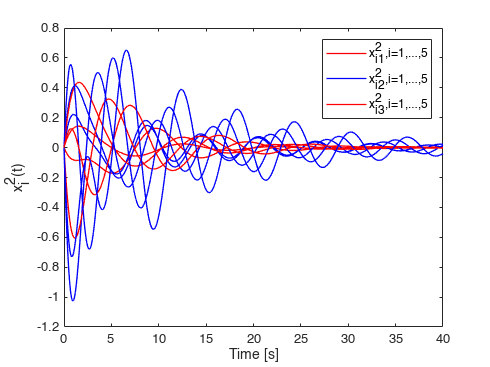


figure
hold on;
for i=1:5
   plot(t,x2(2*i-1,:),'-r','LineWidth',1);
   plot(t,x2(2*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i^2(t)';
box on;
legend({'x_{i1}^2,i=1,\ldots,5','x_{i2}^2,i=1,\ldots,5','x_{i3}^2,i=1,\ldots,5'},"NumColumns",1)

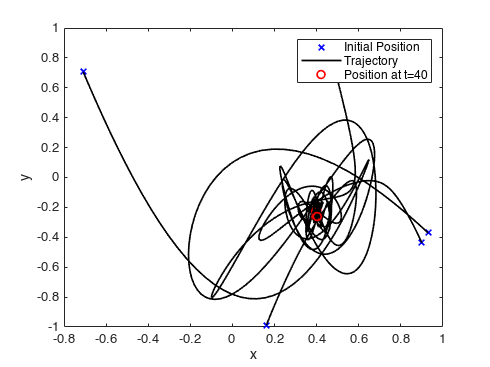



figure
hold on;
for i=1:5
   plot(x1(2*i-1,1),x1(2*i,1),'xb','LineWidth',1.25);
   plot(x1(2*i-1,:),x1(2*i,:),'-k','LineWidth',1.25);
   plot(x1(2*i-1,end),x1(2*i,end),'or','LineWidth',1.25);
end
xlabel 'x'; ylabel 'y';
box on
legend({'Initial Position','Trajectory','Position at t=40'},"NumColumns",1)

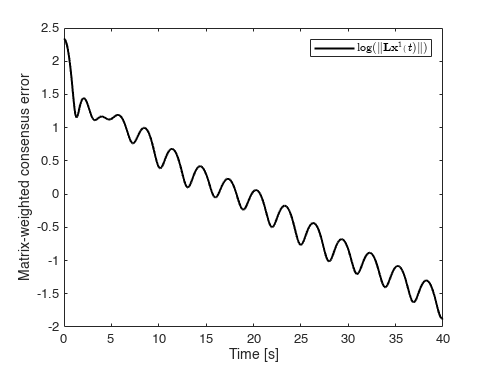


figure
plot(t,log(e)','-k','LineWidth',1.5)
xlabel 'Time [s]'; ylabel 'Matrix-weighted consensus error';
box on; 
legend({'$\log(\|\mathbf{L}\mathbf{x}^1(t)\|)$'},"Interpreter",'latex',"NumColumns",1)

function dx = consensus(t,x)
    global L d
    % kp = 1; kv = .5; Unstable
    kp = 0.35; kv = 1; 
    dx1 = x(d*5+1:10*d,1);
    dx2 = -kp*L*x(1:5*d,1)-kv*dx1;
    dx = [dx1;dx2];
end